# **Relatório do Laboratório de Sinais e Sistemas**

**Q1.1**

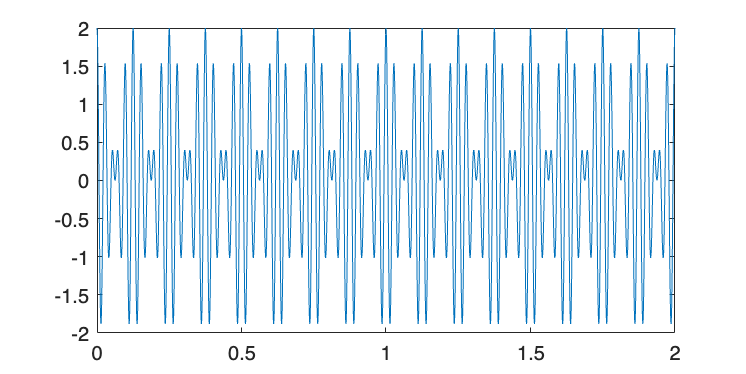

samplerateQ1 = 16e3; % Hz
t = (0:1/samplerateQ1:2); % s
f1 = 32; % Hz
f2 = 40; % Hz
x = cos(2*pi*f1*t) + cos(2*pi*f2*t);
figure('Units', 'pixels', 'Position', [0, 0, 1000, 500]); 
plot(t,noteSeq)

%[xi, yi] = ginput;
%period = mean(diff(xi))

Teoricamente, o período fundamental do sinal é o menor múltiplo comum (MMC) dos períodos fundamentais de cada cosseno.

Ao trabalhar com números racionais (como os períodos fundamentais de cada cosseno, que são o inverso das suas frequências), temos:


$$\text{MMC} = \frac{\text{MMC dos numeradores (= 1)}}{\text{MDC dos denominadores}}$$


function mmc = LCM(a,b)
    [num_a, den_a] = rat(a)
    [num_b, den_b] = rat(b)
    mmc = (lcm(num_a, num_b))/(gcd(den_a, den_b))
end
theoretical_period = LCM(1/f1, 1/f2)

num_a = 1

den_a = 32

num_b = 1

den_b = 40

mmc = 0.1250

theoretical_period = 0.1250

O período que medimos, como a média das diferenças subsequentes entre "localizações periódicas" no sinal, concorda com o período teórico que calculámos acima.

% "Localizações Periódicas" é muito mau ahhahah tenho de mudar

**Q1.2**

period_in_samples = LCM(theoretical_period, 1/samplerateQ1) * samplerateQ1

num_a = 1

den_a = 8

num_b = 1

den_b = 16000

mmc = 0.1250

period_in_samples = 2000

Direct measurement:

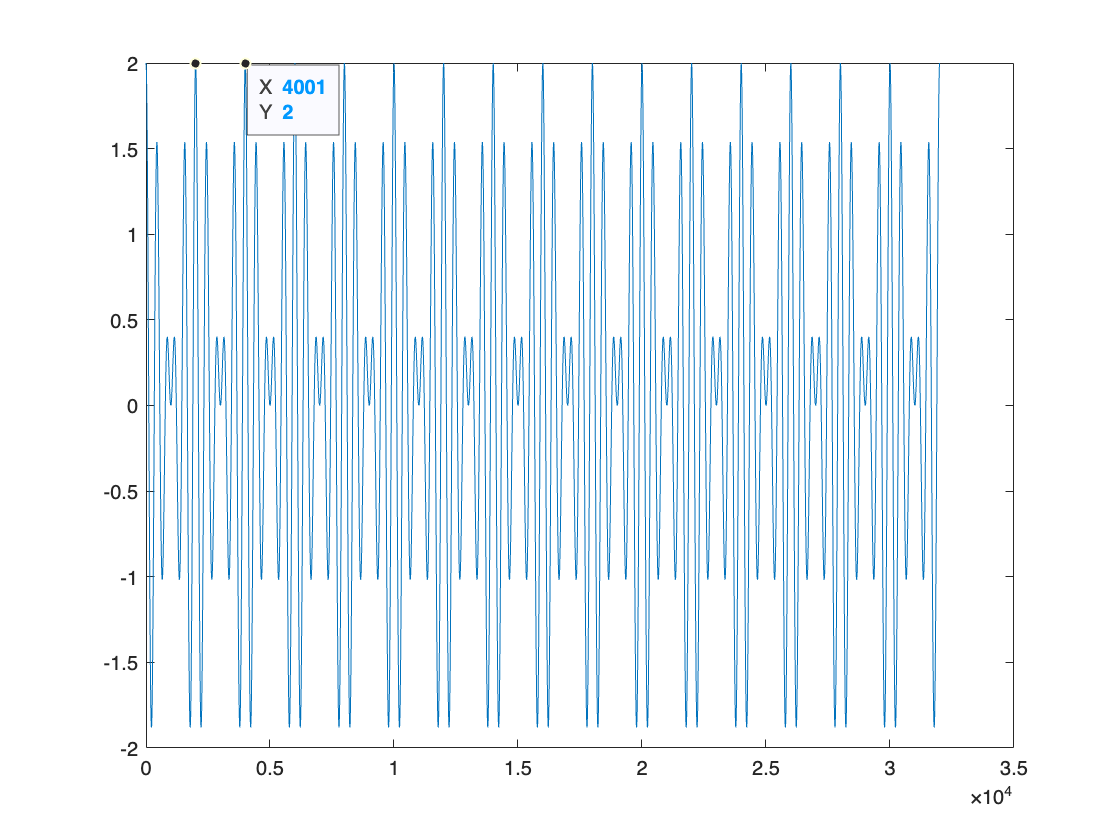

plot(x)

%meter foto com os pontos

y = downsample(x,3);
period_in_samples_y = LCM(theoretical_period, 1/(samplerateQ1/3))*samplerateQ1/3

num_a = 1

den_a = 8

num_b = 3

den_b = 16000

mmc = 0.3750

period_in_samples_y = 2000

Why does this only seemingly disagree with direct measurement from `plot(y)`?

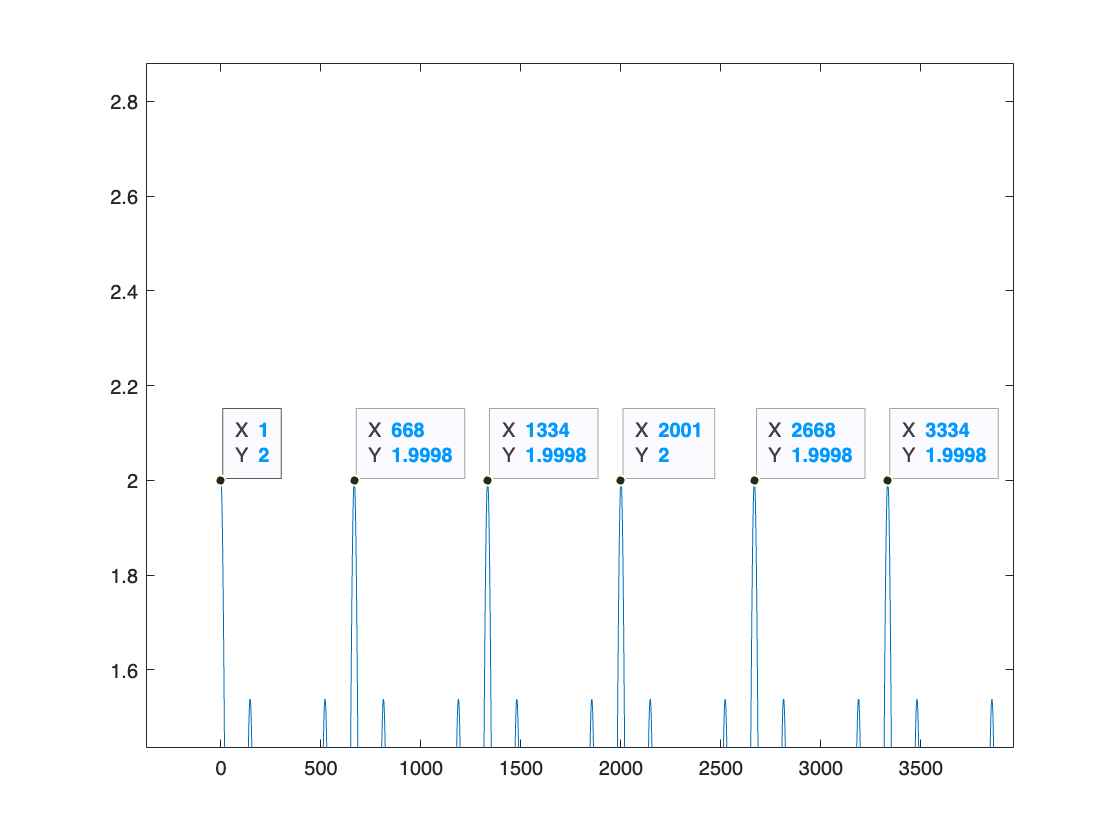

plot(y);

%[xxx,yyy] = ginput;
%measured_period_samples_y = diff(xxx)
% Cenas a mencionar:
% 1) fator pelo qual diminuimos sampling rate = fator pelo qual aumentamos
% período, no tempo MAS como # de samples/tempo também diminui pelo mesmo
% fator,  (T' = 3T MAS n'/T' = (1/3) *n/T
% 2) cena sobre o ponto não apanhar ali mm o pico
% meter foto com os pontos

Teoricamente diferem por causa do domínio, o medido terá que ser um inteiro

**Q1.3**

A4 = 440; % Hz
function frequency = noteFrequencyFromHalfsteps(no_halfsteps)
    A4 = 440; % Hz
    ratio = 2^(1/12);    
    frequency = A4 * ratio^no_halfsteps;
end

C4 = noteFrequencyFromHalfsteps(-9);
E4 = noteFrequencyFromHalfsteps(-5);
Fs4 = noteFrequencyFromHalfsteps(-3);
G4 = noteFrequencyFromHalfsteps(-2);
B4 = noteFrequencyFromHalfsteps(2);
F4 = noteFrequencyFromHalfsteps(-4);

Use the `seqsin` function to generate a sequence of sinusoids and silence gaps. Create x as the following sequence and listen to the resulting signal:


$$\text{R(0.7), E4(0.25), E4(0.25), F4(0.25), F\#4(0.5), A4(0.25),} \\

\text{F\#4(0.25), A4(0.25), F\#4(0.25), F\#4(0.25), F4(0.25),} \\

\text{E4(0.25), B4(0.25), E4(0.25), E4(0.5), R(0.7)}$$


noteSeq = seqsin(samplerateQ1, 0, 0.7, E4, 0.25, E4, 0.25, F4, 0.25, Fs4, 0.5, A4, 0.25, ...
            Fs4, 0.25, A4, 0.25, Fs4, 0.25, Fs4, 0.25, F4, 0.25, ...
            E4, 0.25, B4, 0.25, E4, 0.25, E4, 0.5, 0, 0.7);
soundsc(noteSeq, samplerateQ1)

**Q1.4**

samplerate=16e3

samplerate = 16000

u = @(t) (t >= 0);
t = (-4:1/samplerate:4);

O valor do degrau unitário muda em t=0, assim, para u(at+b) obtêm-se o valor para a mudança de t=-b/a.

se a<0 u(at+b) = u(-t-t0), 

se a>0 u(at+b) = u(t-to)

a=rand

a = 0.0838

b=rand

b = 0.2290

t0=-b/abs(a)

t0 = -2.7317

sinal_a = sign(a)

sinal_a = 1

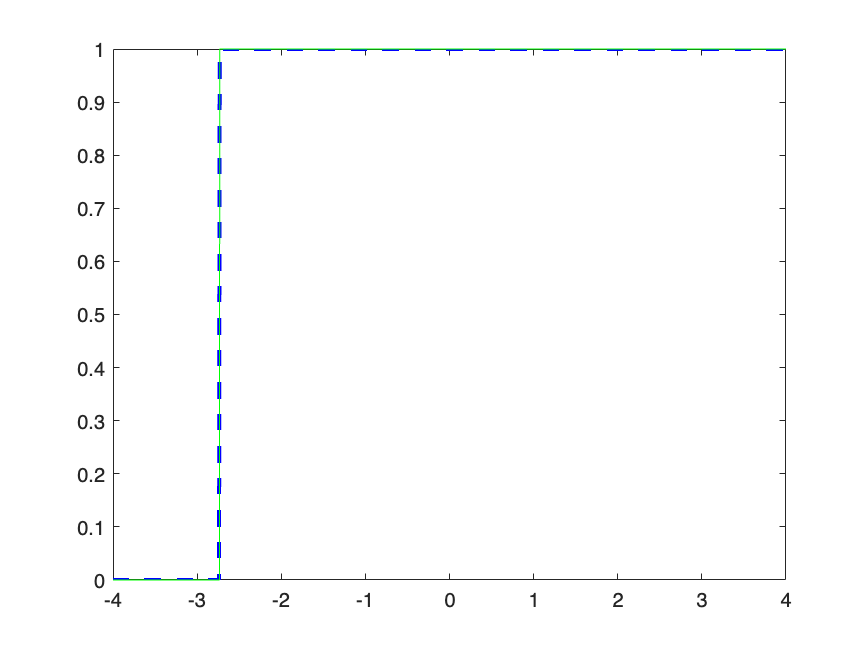

plot(t,u(a*t+b),'b--', 'LineWidth', 2); hold on
plot(t, u(sinal_a*t-t0),"g"); hold off

% relatório por varios lado a lado

s = @(t) (t >= 0).*t;                   % Unit ramp
uD = @(t,D) (1/D)*(s(t+D/2)-s(t-D/2));  % Approximate unit step
duD = @(t,D,h) (uD(t+h/2,D)-uD(t-h/2,D))/h; % Numeric derivative
deltaD = @(t,D) duD(t,D,1e-6);          % Approximate unit impulse

O sinal tem valores diferentes de zero entre t0-D/2 e t0+D/2:

D = rand

D = 0.9133

T = D/2 

T = 0.4567

t00 = rand

t00 = 0.1524

%dt para aumentar a resolução, aka + data points do que o default 1 em 1
dt=D/1000

dt = 9.1334e-04

t2 = t00-T-D*1000:dt:t00+T+D*1000

t2 =  -913.6417 -913.6407 -913.6398 -913.6389 -913.6380 -913.6371 -913.6362 -913.6353 -913.6343 -913.6334 -913.6325 -913.6316 -913.6307 -913.6298 -913.6289 -913.6280 -913.6270 -913.6261 -913.6252 -913.6243 -913.6234 -913.6225 -913.6216 -913.6206 -913.6197 -913.6188 -913.6179 -913.6170 -913.6161 -913.6152 -913.6143 -913.6133 -913.6124 -913.6115 -913.6106 -913.6097 -913.6088 -913.6079 -913.6069 -913.6060 -913.6051 -913.6042 -913.6033 -913.6024 -913.6015 -913.6006 -913.5996 -913.5987 -913.5978 -913.5969


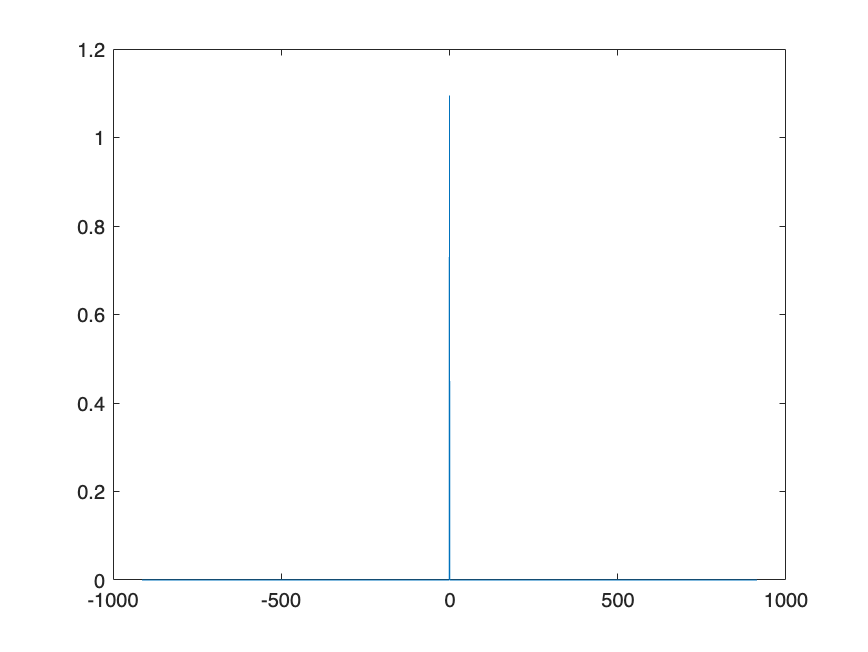

plot(t2, deltaD(t2-t00,D)); hold off

% meter -0.5 a 1.5 no yy

a = 0.5

a = 0.5000

t3 = (-5:0.001:5)

t3 =    -5.0000   -4.9990   -4.9980   -4.9970   -4.9960   -4.9950   -4.9940   -4.9930   -4.9920   -4.9910   -4.9900   -4.9890   -4.9880   -4.9870   -4.9860   -4.9850   -4.9840   -4.9830   -4.9820   -4.9810   -4.9800   -4.9790   -4.9780   -4.9770   -4.9760   -4.9750   -4.9740   -4.9730   -4.9720   -4.9710   -4.9700   -4.9690   -4.9680   -4.9670   -4.9660   -4.9650   -4.9640   -4.9630   -4.9620   -4.9610   -4.9600   -4.9590   -4.9580   -4.9570   -4.9560   -4.9550   -4.9540   -4.9530   -4.9520   -4.9510


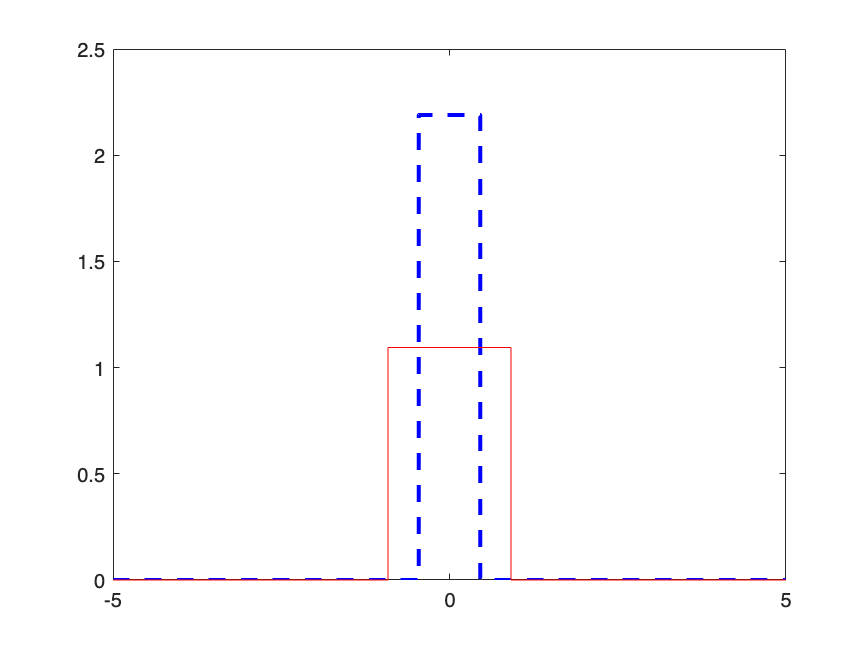

deltaA = deltaD(t3, D)/abs(a);
plot(t3, deltaA, "b--", "LineWidth",2); hold on
plot(t3, deltaD(a*t3, D), "r"); hold on